# Testing real scanned-OCT data on phantoms

At first read the data

D1 = fopen('C:\MatkivskiyV\science\article8\ab_comp_matlab\data\data_from_setup\dot3_stab.dat');
A = fread(D1,1024*256*256*2,'single');
fclose(D1);

Obtains complex data from single. There is a strange tilted component of the image (there may be a reflected component). 

B = A(1:2:end) + 1j*A(2:2:end);
C = reshape(B,[256,256,1024]);

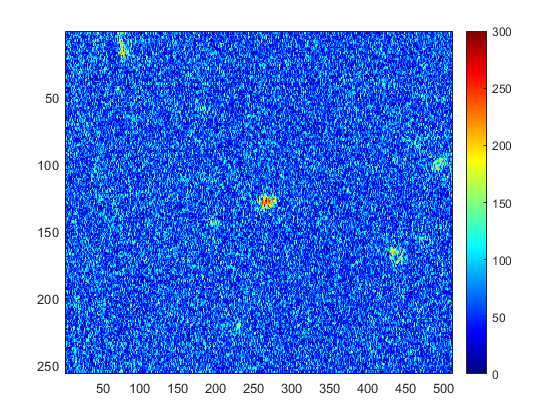

E0 = squeeze(sum(C(:,87,1:2:end),2));
figure(); imagesc(abs(E0)); colorbar ; colormap(jet); caxis([0 300])

C2 = C(:,:,1:2:end);
C3 = C2;
clear C

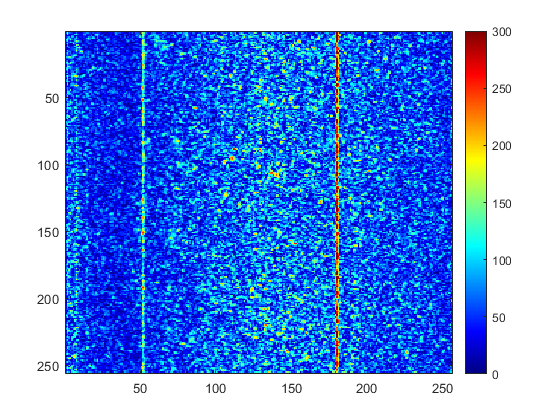

C2 = C3;
B = C2(:,:,512);
figure(); imagesc(abs(B)); colorbar ; colormap(jet); caxis([0 300])

dfin = zeros(511,1);
for it = 1:511
    B1 = C2(50:200,55:165,it);
    B2 = C2(50:200,55:165,it+1);
    prodt = B1.*conj(B2);
    dfi = sum(prodt(:));
    dfin(it) = dfi;
    C2(50:200,55:165,it+1) = C2(50:200,55:165,it+1).*conj(dfi)./abs(dfi);
end


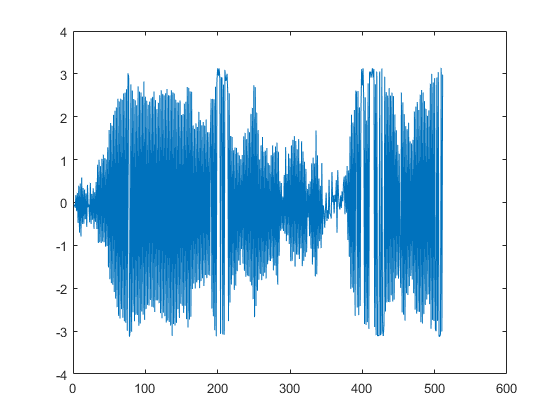

figure(); plot(angle(dfin))

E0 = squeeze(sum(C2(:,87,:),2));

Ploting the fourier transformation for all field and for the part with a scaterrer

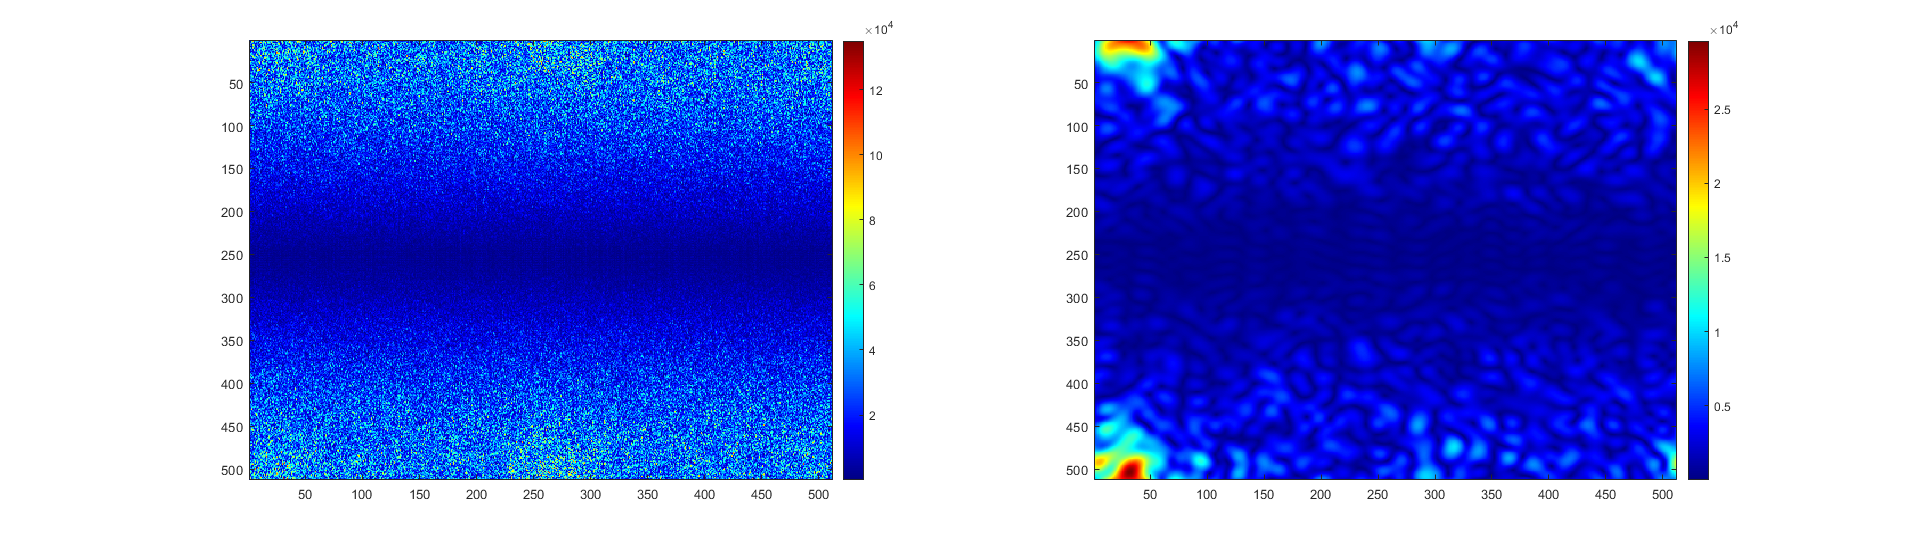

E0 = squeeze(sum(C2(:,87,:),2));
E = zeros(512,512,'single');
E(257-128:257+127,:) = E0;
Etemp = zeros(512,512,'single');
Etemp(256-16:256+16,266-16:266+16) = 1;
twoplots(abs(FTS(E)),abs(FTS(E.*Etemp)));

% clear A B C E0  

The Fourier spectr is found. It's not bed enought, but the spectrum is shifted.

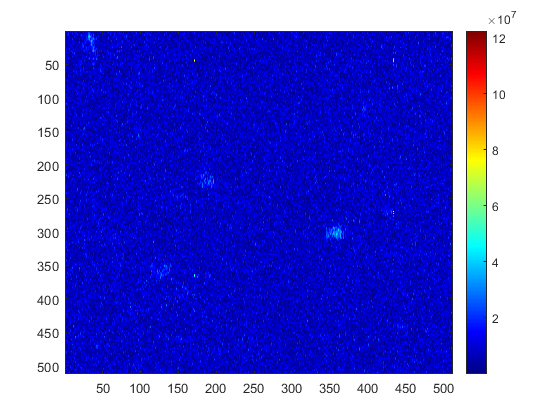

fE = FTS(E0);
fE = circshift(fE,[135 -20]);
fE2 = zeros(512,512);
fE2(129:384,:) = fE(:,:);
E =  circshift((FTS(fE2)),[43 111]);
figure(); imagesc(abs(E)); colorbar ; colormap(jet);

Read the aberrated data

D1 = fopen('C:\MatkivskiyV\science\article8\ab_comp_matlab\data\data_from_setup\USAF_4_ab_2.dat');
D = zeros(1024,256,256,'single');
A = fread(D1,1024*256*256*2,'single');
fclose(D1);

B = A(1:2:end) + 1j*A(2:2:end);
C = reshape(B,[256,256,1024]);

E0a = squeeze(sum(C(:,108:112,1:2:end),2));
figure(); imagesc(abs(E0a)); colorbar ; colormap(jet);

Ea = zeros(size(E0a),'single');
Ea(73:203,228:444) = E0a(73:203,228:444);
figure(); imagesc(abs(Ea)); colorbar ; colormap(jet);
clear A B C E0a

function h2 = twoplots(T1,T2,title1,title2)
    if nargin<3
        title1 = '';
        title2 = '';
    end

    h2 = figure();
    subplot(1,2,1);
    imagesc(T1); colormap(jet); colorbar();
    title(title1)
    subplot(1,2,2);    
    imagesc(T2); colormap(jet); colorbar();
    title(title2)
    set(h2,'Units','normalized','position',[0 0 1 .5])
end